Homework #05

## 1

1a)

So for our least sqs solution, we want to minimize the distance between Ax and b,$|Ax-b|^2$, which is = $(Ax-b)^T(Ax-b)$

So we have an optimization problem and want to look for where the derivative = 0:


$$\frac{d}{dx}(Ax-b)^T(Ax-b)$$



$$=\frac{d}{dx}(x^TA^TAx-b^TAx-x^TA^Tb+b^Tb)$$



$$=2(A^TAx-A^Tb)=0
$$


Therefore, $A^TAx=A^Tb$ and $x=(A^TA)^{-1}(A^Tb)$

1b)

A=[ 4, 1, 3; -4, -2, -5; 3, -1, -4; 0, 4, -1];
b=[ 0; 5; -1; -2];

x=inv(A.'*A)*(A.'*b)

x =    -0.4023
   -0.5666
   -0.0704


1c)

residual=(A*x)-b

residual =    -2.3868
   -1.9059
    0.6412
   -0.1959


Because although this least sqs solution minimizes the distance between Ax and b, it can not get it to 0 since there is no exact solution/intersection since there are more equations than actual unknowns.

1d)

disp('norm of residual:')

norm of residual:


disp(norm(residual))

    3.1271



disp('norm of b:')

norm of b:


disp(norm(b))

    5.4772



I would consider the residual large since we can compare the residual as a proportion of the right hand side, b, and it seems to be about 60% (a significant proportion) of the magnitude of b.

1e)

x=A\b

x =    -0.4023
   -0.5666
   -0.0704


Matlab's function gives the same result

## 2

2a)

A=[-0.4, 0.2, -0.7; 
    0.8, -0.7, -0.1];
b=[-1; 
    0.5];

[U, sigma, V]=svd(A)

U =    -0.5001   -0.8659
    0.8659   -0.5001


sigma =     1.1684         0         0
         0    0.6817         0


V =     0.7641   -0.0788   -0.6403
   -0.6044    0.2595   -0.7532
    0.2255    0.9625    0.1506


[pic of 2a]

% replace me-----
sigma_pseudo=sigma.^(-1);
sigma_pseudo(sigma==0)=0;
sigma_pseudo=sigma_pseudo.'

sigma_pseudo =     0.8558         0
         0    1.4669
         0         0


disp(sigma_pseudo*U.')

   -0.4280    0.7411
   -1.2702   -0.7336
         0         0



disp(V*sigma_pseudo*U.')

   -0.2270    0.6241
   -0.0709   -0.6383
   -1.3191   -0.5390



2b)

A_pseudo=[-0.2270 0.6241;
    -0.0709 -0.6383;
    -1.3191 -0.5390]

A_pseudo =    -0.2270    0.6241
   -0.0709   -0.6383
   -1.3191   -0.5390



x=A_pseudo*b

x =     0.5391
   -0.2482
    1.0496


2c)

disp('using pinv():')

using pinv():


x2=pinv(A)*b

x2 =     0.5390
   -0.2482
    1.0496


disp('using A\b:')

using A\b:


x3=A\b

x3 =     0.7500
         0
    1.0000


We get the same result if Matlab's pseudoinverse function, pinv() is used, but since there are technically infinite solutions to this sytem, Matlab's A\b will just give a solution that might not be the same as the one gotten using A's pseudoinverse.

However, their norms similar:

disp('norm of x from calculated pseudoinverse:')

norm of x from calculated pseudoinverse:


disp(norm(x))

    1.2058



disp('norm of x from Matlab pinv():')

norm of x from Matlab pinv():


disp(norm(x))

    1.2058



disp('norm of x from Matlab A\b:')

norm of x from Matlab A\b:


disp(norm(x3))

    1.2500



## 3

3a)

A=[-1.3, -0.3; 0.75, -0.52];

[U, sigma, V]=svd(A)

U =    -0.8662    0.4997
    0.4997    0.8662


sigma =     1.5008         0
         0    0.6003


V =      1     0
     0    -1


ans =      1     0
     0    -1


V =      1     0
     0    -1



$$A=U V^T V \Sigma V^T$$



$$A=\left[{\begin{array}{cc}
-0.8662 && 0.4997 \\
0.4997 && 0.8662 \\
\end{array}}\right]

\left[{\begin{array}{cc}
1 && 0 \\
0 && -1 \\
\end{array}}\right]

\left[{\begin{array}{cc}
1 && 0 \\
0 && -1 \\
\end{array}}\right]

\left[{\begin{array}{cc}
1.5008 && 0 \\
0 && 0.6003 \\
\end{array}}\right]

\left[{\begin{array}{cc}
1 && 0 \\
0 && -1 \\
\end{array}}\right]$$


3b)

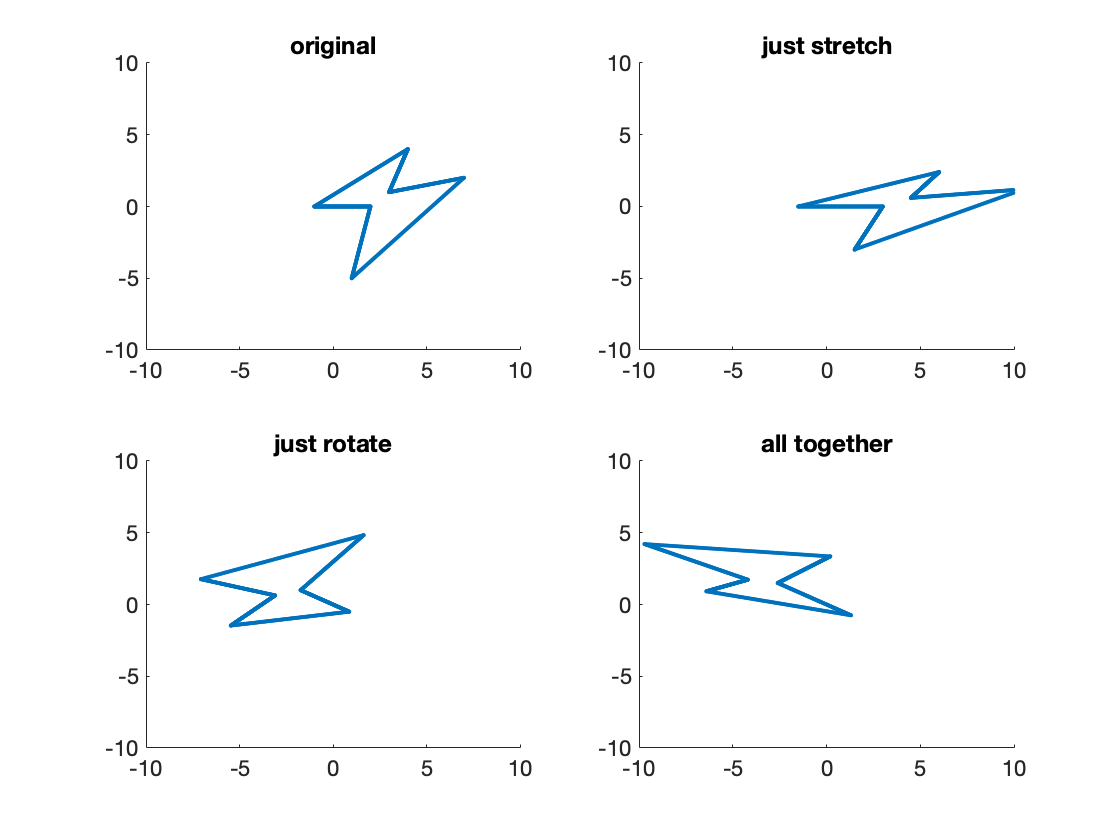

Corners=[1, 7, 3, 4,-1, 2;
-5, 2, 1, 4, 0, 0];

% draw lines, made of sets of points, between each two consecutive corners:
R=[0:0.01:1;0:0.01:1];
NR=length(R);
Ncorners=length(Corners(1,:));
start=1;
X=zeros(2, NR);
for j=1:Ncorners
  jm1=j-1;
  % the first line is between the last and first corners:
  if j==1
    jm1=Ncorners;
  end
  X(:,start:start+NR-1)=Corners(:,jm1)+R.*(Corners(:,j)-Corners(:,jm1));
  start=start+length(R(1,:));
end
NX=length(X(1,:));

% rotate and stretch matrices
A_rotate = U*V.';
A_stretch = V*sigma*V.';

figure
subplot(2,2,1)
hold on; xlim([-10 10]); ylim([-10 10]);
title('original')
plot(X(1,:),X(2,:),'.')

subplot(2,2,2)
hold on; xlim([-10 10]); ylim([-10 10]);
title('just stretch')
for i=1:NX
  X_stretch(:,i)=A_stretch*X(:,i);
end
plot(X_stretch(1,:),X_stretch(2,:),'.')


subplot(2,2,3)
hold on; xlim([-10 10]); ylim([-10 10]);
title('just rotate')
for i=1:NX
  X_rotate(:,i)=A_rotate*X(:,i);
end
plot(X_rotate(1,:),X_rotate(2,:),'.')

subplot(2,2,4)
hold on; xlim([-10 10]); ylim([-10 10]);
title('all together')
for i=1:NX
  X_all(:,i)=A_rotate*A_stretch*X(:,i);
end
plot(X_all(1,:),X_all(2,:),'.')

3d)

Using direct scaling of M:

T=[1, 0, 5;
    0, 1, -0.5;
    0, 0, 1]

T =     1.0000         0    5.0000
         0    1.0000   -0.5000
         0         0    1.0000


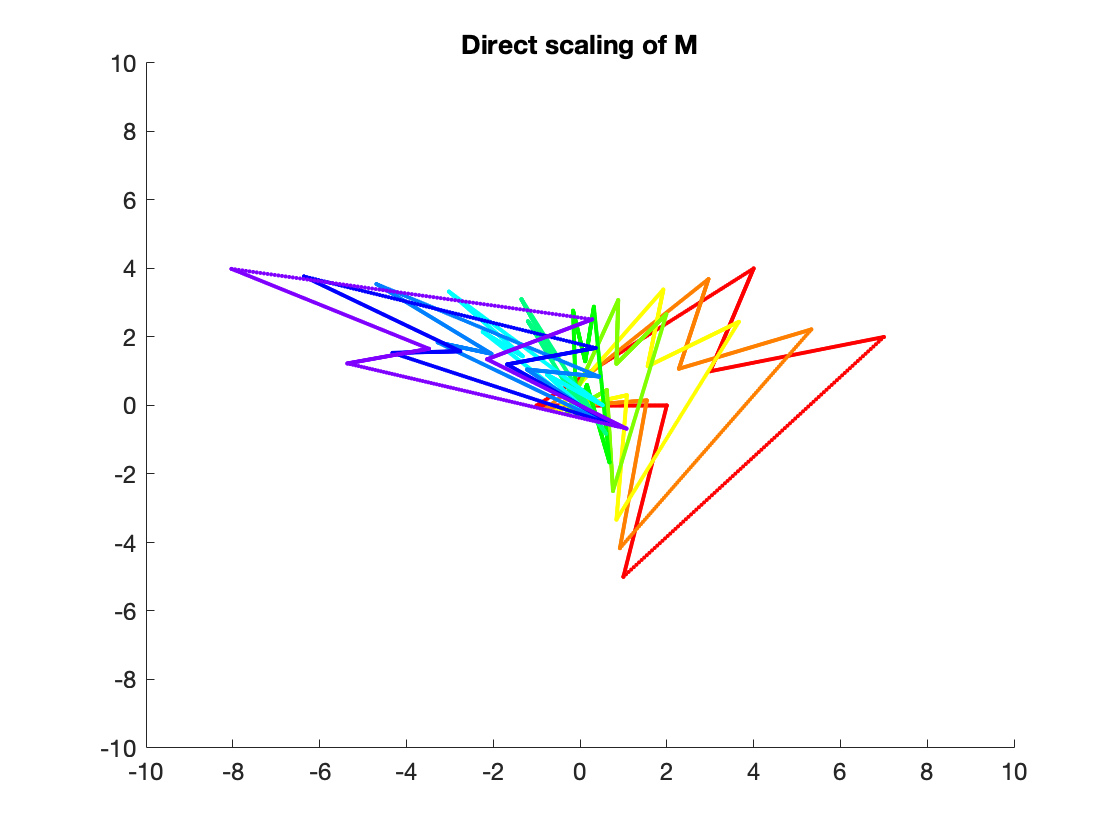

M=T*[A_rotate [0;0]; [0 0 0]]*[A_stretch [0;0]; [0 0 0]];
M=M(1:2,1:2);

I=eye(2,2);
figure; title('Direct scaling of M')
hold on;xlim([-10 10]); ylim([-10 10]);
color={[1 0 0] [1 0.5 0] [1 1 0] [0.5 1 0] [0 1 0] [0 1 0.5] [0 1 1] [0 0.5 1] [0 0 1] [0.5 0 1]};
for tn=0:1:9
    t=tn/10;
    for i=1:NX
        X_M1(:, i)=(t.*M + (1-t).*I)*X(:,i);  
    end
    plot(X_M1(1,:),X_M1(2,:),'.', 'Color', color{tn+1})
    
end

Using polar decomposition:

theta=acos(A_rotate(1,1));
disp(theta)

    2.6183



theta_degree=theta*180/pi

theta_degree = 150.0184

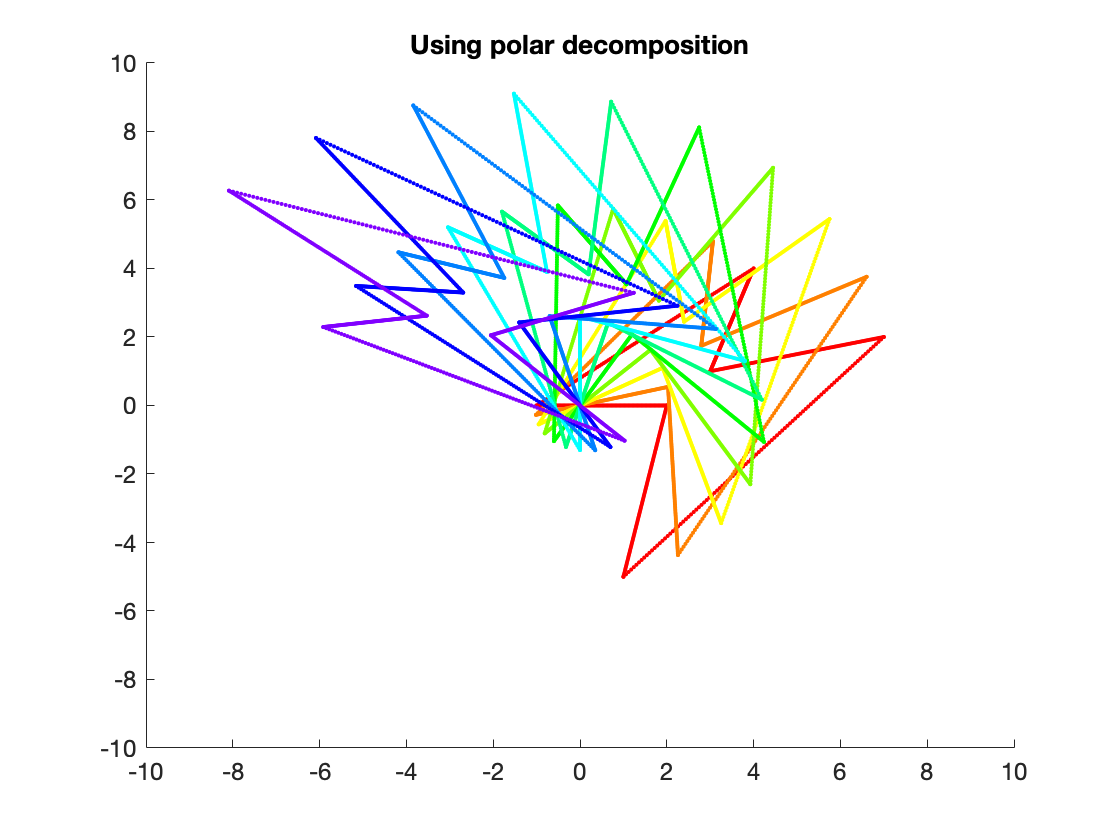

S=[A_stretch [0;0]; [0 0 0]];

I=eye(3,3);
figure; title('Using polar decomposition')
hold on;xlim([-10 10]); ylim([-10 10]);
color={[1 0 0] [1 0.5 0] [1 1 0] [0.5 1 0] [0 1 0] [0 1 0.5] [0 1 1] [0 0.5 1] [0 0 1] [0.5 0 1]};
for tn=0:1:9
    t=tn/10;
    for i=1:NX
        R_t_theta=[cos(theta*t), -sin(theta*t), 0; 
              sin(theta*t), cos(theta*t), 0;
              0,            0,            0];
        M2=(t.*T + ((1-t).*I))...
            *R_t_theta...
            *(t.*S + ((1-t).*I));
        X_M2(:,i)=M2(1:2, 1:2)*X(:,i); 
    end
    plot(X_M2(1,:),X_M2(2,:),'.', 'Color', color{tn+1})
    
end